# AAE 564 - Homework 1 - Exercise 7 - Joseph Le

## Parameters and Initial Conditions

P1 = [2 1 1 1 1 1];
P2 = [2 1 1 1 0.99 1];
P3 = [2 1 0.5 1 1 1];
P4 = [2 1 1 1 0.5 1];

IC1 = [0 -10 10 0 0 0];
IC2 = [0 10 10 0 0 0];
IC3 = [0 -90 90 0 0 0];
IC4 = [0 -90.01 90 0 0 0];
IC5 = [0 100 100 0 0 0];
IC6 = [0 100.01 100 0 0 0];
IC7 = [0 179.99 0 0 0 0];

case1 = num2cell([P1,IC1]);
case2 = num2cell([P1,IC2]);
case3 = num2cell([P1,IC3]);
case4 = num2cell([P1,IC7]);

case5 = num2cell([P4,IC1]);
case6 = num2cell([P4,IC2]);
case7 = num2cell([P4,IC3]);
case8 = num2cell([P4,IC4]);

## Case 1: *P1, IC1*

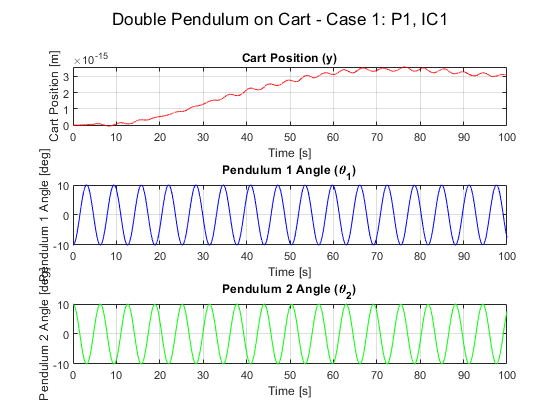

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case1{:}); % pull parameters and initial conditions for case 1
% change angle ICs to radians
theta10 = deg2rad(theta10); 
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);
% total mass
mt = m0 + m1 + m2;

% initialize time vector
t = linspace(0,100,2^14);

% initial conditions vector
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];
init = [q0; qdot0];

% running ODE45 on the function
[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);

% plotting results
sgtitle("Double Pendulum on Cart - Case 1: P1, IC1")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 2: *P1, IC2*

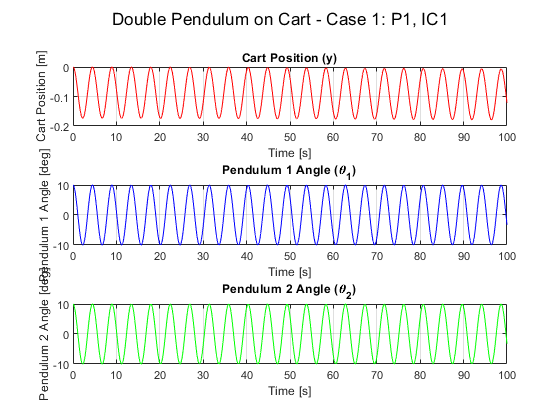

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case2{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 2: P1, IC2")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 3: *P1, IC3*

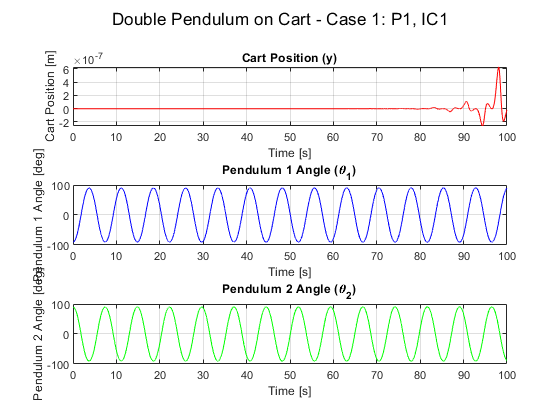

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case3{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 3: P1, IC3")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 4: *P1, IC7*

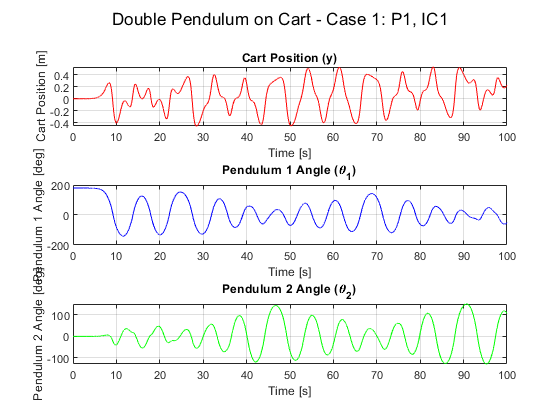

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case4{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 4: P1, IC7")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 5: *P4, IC1*

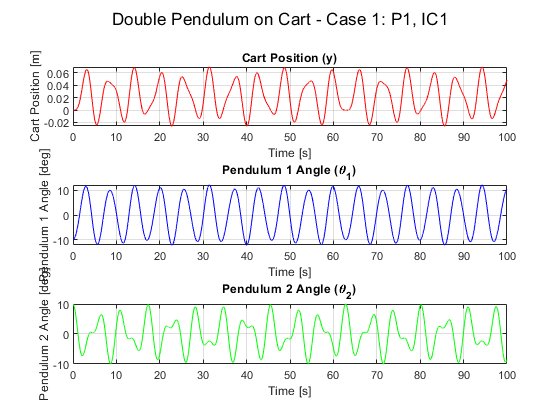

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case5{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 5: P4, IC1")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 6: *P4, IC2*

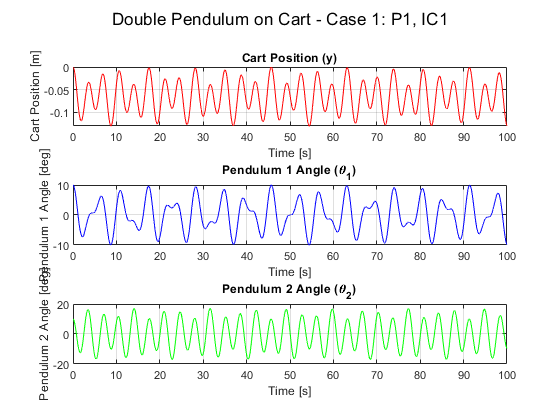

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case6{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 6: P1, IC2")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 7: *P4, IC3*

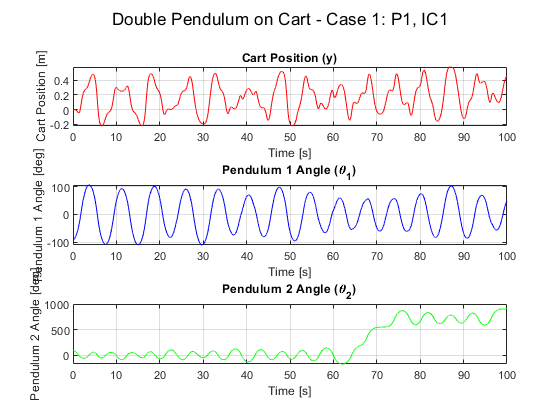

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case7{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 7: P4, IC3")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## Case 8: *P4, IC4*

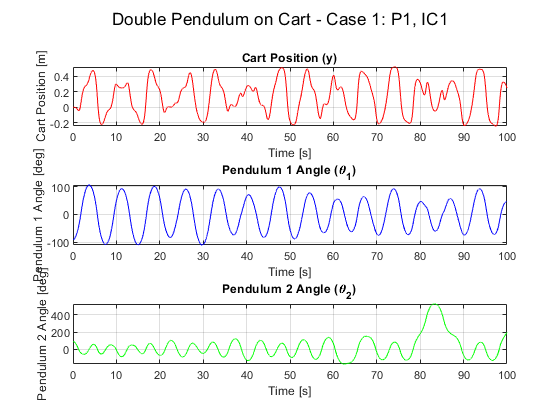

[m0, m1, m2, l1, l2, g, y0, theta10, theta20, ydot0, theta1dot0, theta2dot0]...
    = deal(case8{:});
theta10 = deg2rad(theta10);
theta20 = deg2rad(theta20);
theta1dot0 = deg2rad(theta1dot0);
theta2dot0 = deg2rad(theta2dot0);

mt = m0 + m1 + m2;

t = linspace(0,100,2^14);
q0 = [y0;theta10;theta20]; qdot0 = [ydot0;theta1dot0;theta2dot0];

init = [q0; qdot0];

[t,x] = ode45(@(t,x) xfun(x, m0, m1, m2, l1, l2, g, mt),t,init);
sgtitle("Double Pendulum on Cart - Case 8: P4, IC4")
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on

## ODE Matrix Function

function dxdt = xfun(x, m0, m1, m2, l1, l2, g, mt)
u = 0;
M = [mt, -m1*l1*cos(x(2)), -m2*l2*cos(x(3));
    -m1*l1*cos(x(2)), m1*l1^2, 0;
    -m2*l2*cos(x(3)), 0, m2*l2^2];

G = [m1*l1*sin(x(2))*x(5)^2 + m2*l2*sin(x(3))*x(6)^2;
    m1*l1*g*sin(x(2));
    m2*l2*g*sin(x(3))];

W = [1;0;0];

q = x(1:3);
qdot = x(4:6);
qddot = inv(M)*(W*u-G);

dxdt = [qdot; qddot];
end